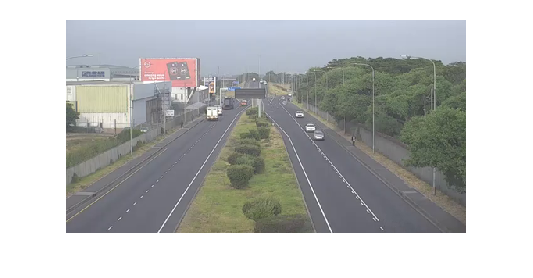

load("cams_info.mat")
imshow(cams_info{1}.rgb)


depth_img1 = cams_info{1}.depth;  % Depth image
rgb_img1=cams_info{1}.rgb;
f1 = cams_info{1}.focal_lenght;  % Focal lengths

[height, width, ~] = size(depth_img1);  % Dimensões da imagem RGB

% Assuming the principal point is at the image center (if not provided)
c_x = width / 2

c_x = 256

c_y = height / 2

c_y = 136

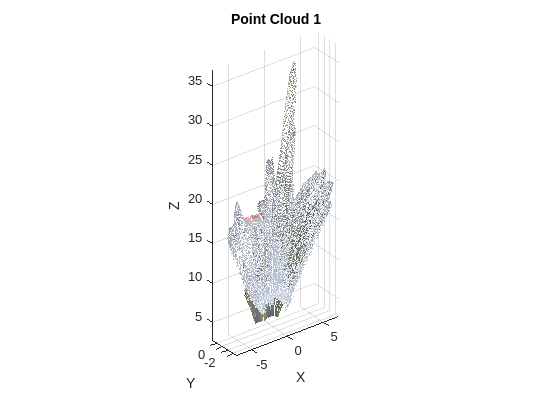


depth_flat1 = depth_img1(:);
colors1 = reshape(rgb_img1, [], 3);  % Transformar a imagem RGB em uma matriz de cores


% Criar uma grade de pixels
[x, y] = meshgrid(1:width, 1:height);
% Achatar as imagens para vetores
x_flat = x(:);
y_flat = y(:);

X1 = (depth_flat1 .* (x_flat - c_x)) / f1;
Y1 = (depth_flat1 .* (y_flat - c_y)) / f1;
Z1 = depth_flat1;

figure;
% Plotar o ponto 3D colorido
scatter3(X1, Y1, Z1, 1, colors1, 'filled');
colormap('gray')
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud 1');
axis equal;